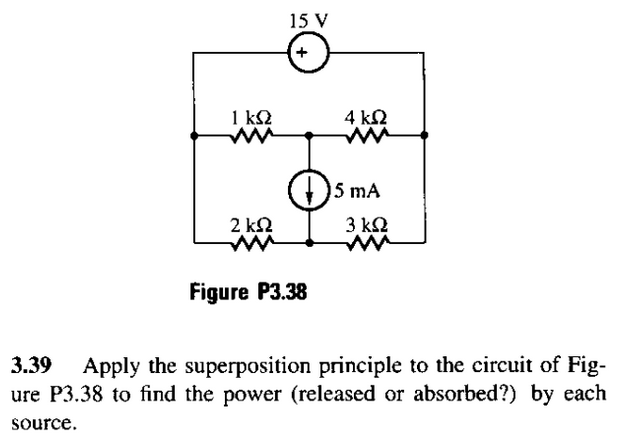

De acuerdo con el teorime de la superposicion , dice que tenemos que analizar tantos circuitos como fuentes tengamos, con las fuentes de tension representadas como un corto circuito, y las fuentes de corriente como un circuito abierto, para asi saber los aportes de cada una al circuito original, de acuerdo con lo dicho anteriormente, tenemos dos circuitos, porque tenemos dos fuentes:

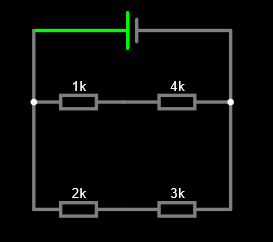

en este caso tenemos resistencias en paralelo, las reducimos para obtener la correinte aportada por la fuente de tension:

clc, clear, close all
format short g

If = 5e-3; %[A]
vf = 15; %[V]
r1 = 1000;
r2 = 2000;
r3 = 3000;
r4 = 4000;

I_vf = vf/(1/(1/(r1+r4)+1/(r2+r3))) %[A]

I_vf =         0.006


Ahora calculamos la diferencia de tension en los nodos donde estaba la fuente de correinte:

v = 15*r1/(r2+r3)-(15*r2/(r2+r3)) %[V]

v =     -3


Ahora corto circuitamos la fuente de tension, y realizamos un divisor de corriente en r2 y r3

i_r3 = (5e-3)*r2/(r2+r3)

i_r3 =         0.002


i_r2 = (5e-3)*r3/(r2+r3)

i_r2 =         0.003


Y asi podemos calcular la tension en la fuente de corriente:

v_if = r2*i_r2+r1*(0.004)

v_if =     10


Finalmente vemos que tenemos una super malla por lo que las corrientes en cada una de las ramas se restan, para asi tener la corriente aportada por la fuente de corriente al circuito original:

ifc = i_r2 - i_r3

ifc =         0.001


i_total = I_vf+ifc

i_total =         0.007


Debido al sentido de la corriente deducimos que la fuente de tension entrega potencia

p_vf = vf*i_total %[W]

p_vf =         0.105


p_if = (v+v_if)*If

p_if =         0.035


Ambas fuentes entregan potencia, lo verificamos en el simulador: